# Problem 2.2a

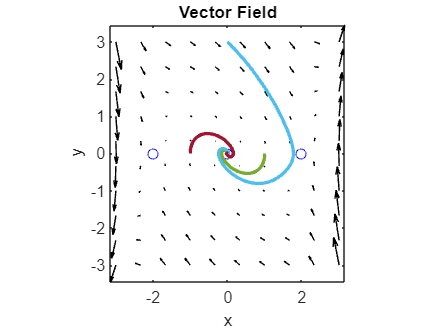

close all; clc

% Create vector field with solutions
x = linspace(-3,3,10);
y = linspace(-3,3,10);
[X,Y] = meshgrid(x,y);
DX = Y;                  % same equation as f
DY = -X + 1/16*X.^5 - Y; % same equation as f
quiver(X,Y,DX,DY,'k');
xlabel('x')
ylabel('y')
axis tight equal;
title("Vector Field")

hold on;

% plot equilibrium points
for y0 = [0 0; 2 0; -2 0]'
    [~, ys] = ode45(@f,[0 10],y0);
    plot(ys(:,1),ys(:,2),'bo')
end

% plot trajectories
for y0 = [1 0; 0 3; -1 0]'
    [~, ys] = ode45(@f,[0 10],y0);
    plot(ys(:,1),ys(:,2),'-','LineWidth',2)
end

hold off;

% linearize the system automatically
syms x y
disp('Jacobian')

Jacobian


J = jacobian([y,-x+1/16*x^5-y],[x,y])

$$J = \left(\begin{array}{cc} 0 & 1\\ \frac{5\,x^{4}}{16}-1 & -1 \end{array}\right)$$


% evaluate jacobian at equilibrium points
Legend=cell(3,1);
iter = 1;
for eq = [0 0; 2 0; -2 0]'
    x0 = eq(1);
    y0 = eq(2);
    disp('===========================')
    disp(['Eq Point: ', num2str([x0 y0])])
    A = subs(J,[x y], [x0 y0])
    lambda = eig(A)
    
    plot(real(lambda),imag(lambda),'x'); hold on
    Legend{iter} = num2str([x0 y0]);
    iter = iter + 1;
end

Eq Point: 0  0


$$A = \left(\begin{array}{cc} 0 & 1\\ -1 & -1 \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -\frac{1}{2}-\frac{\sqrt{3}\,\mathrm{i}}{2}\\ -\frac{1}{2}+\frac{\sqrt{3}\,\mathrm{i}}{2} \end{array}\right)$$

Eq Point: 2  0


$$A = \left(\begin{array}{cc} 0 & 1\\ 4 & -1 \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -\frac{\sqrt{17}}{2}-\frac{1}{2}\\ \frac{\sqrt{17}}{2}-\frac{1}{2} \end{array}\right)$$

Eq Point: -2  0


$$A = \left(\begin{array}{cc} 0 & 1\\ 4 & -1 \end{array}\right)$$

$$lambda = \left(\begin{array}{c} -\frac{\sqrt{17}}{2}-\frac{1}{2}\\ \frac{\sqrt{17}}{2}-\frac{1}{2} \end{array}\right)$$

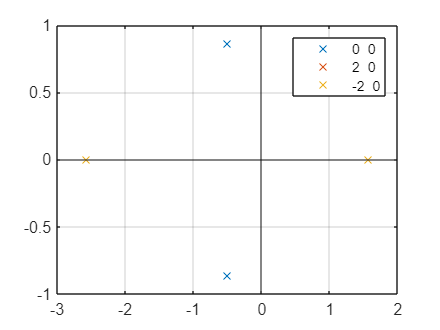

axis on
grid on
yline(0)
xline(0)
legend(Legend)
hold off

function [y_dot] = f(~,y)
y_dot(1,:) = y(2);
y_dot(2,:) = -y(1)+ y(1).^5/16 - y(2);
end